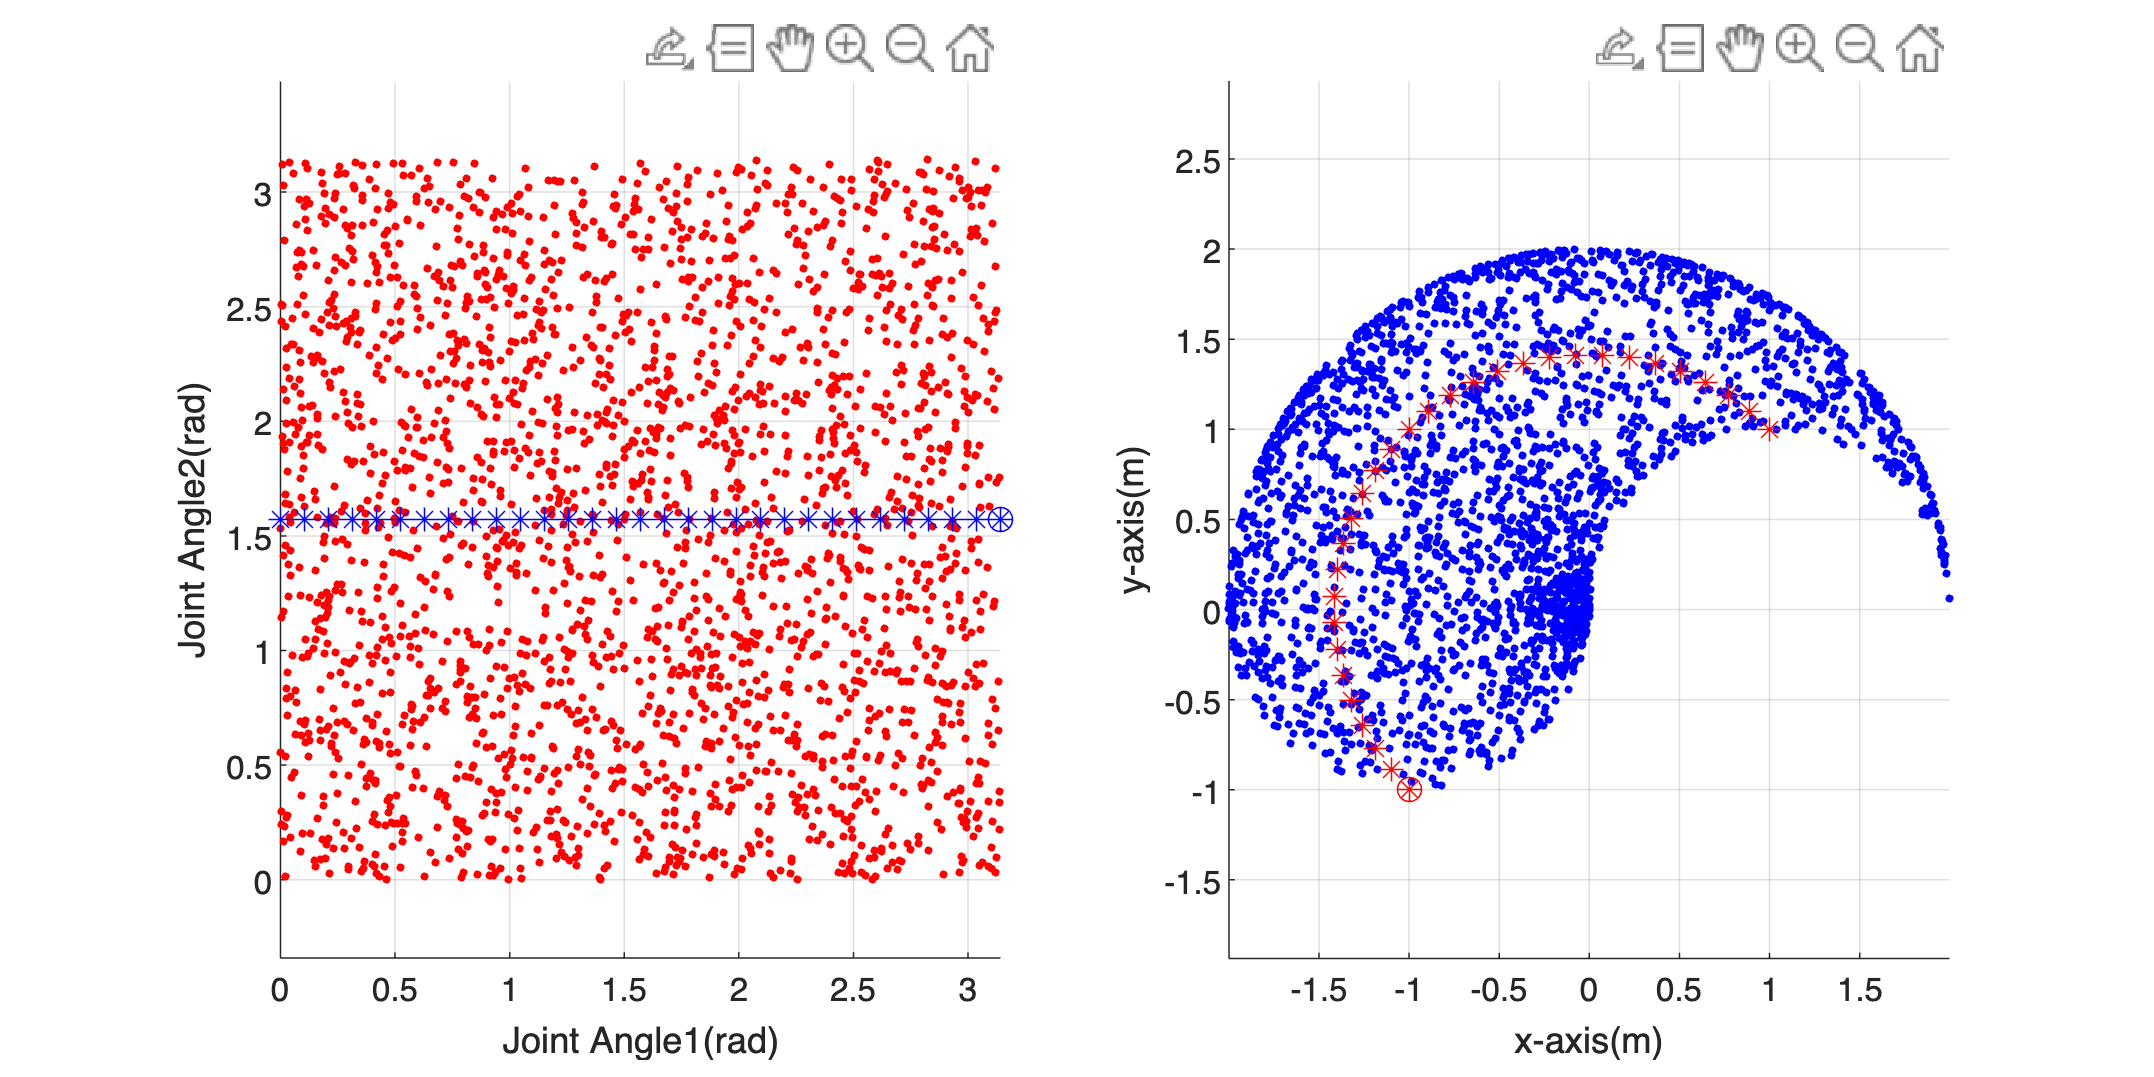

% 关节空间轨迹（无规划）
clc
clear
close all

% ++++++++++++++++++++++++++++++++++++++++++++++++
% 机器人
% Robot by DH parameters
%           theta d   a  alpha offset      
L(1) = Link([0    0   1   0    0],'qlim', [JL1d JL1u]);
L(2) = Link([0    0   1   0    0],'qlim', [JL2d JL2u]);
robot = SerialLink(L, 'name', 'Bot_2links');

% 为每一个关节设置旋转角度限制
JL1u = pi;
JL1d = 0;
JL2u = pi;
JL2d = 0;

% 随机取N个关节空间中的点
N = 500;
N = 2500; 
theta1 = ( JL1d + (JL1u - JL1d)*rand(N,1) ); 
theta2 = ( JL2d + (JL2u - JL2d)*rand(N,1) ); 
% 计算这N个点的末端T矩阵
T1 = robot.fkine([theta1 theta2]);  

% 画出关节空间的取值区域
figure('position',[0,0,1200,600]);

% ++++++++++++++++++++++++++++++++++++++++++++++++
% 关节空间绘图
subplot(1,2,1); 
view([0.40 90.00]); hold on; axis equal; grid
xlabel('Joint Angle1(rad)');  ylabel('Joint Angle2(rad)');

% 画出关节角有效区域
plot3(theta1, theta2, zeros(N), 'r.','MarkerSize',8);

%% 在该区域内取M个点（一个直线）
M = 30;
theta1 = JL1d : (JL1u - JL1d)/M : JL1u; 
theta2 = ones(size(theta1))*pi/2;

%% 计算这M个点的末端T矩阵
T2 = robot.fkine([theta1' theta2']);

%% 画出这M个点，标记最后一个点
plot3(theta1, theta2, zeros(M+1), 'b*','MarkerSize',8);
plot3(theta1(M+1), theta2(M+1), 0, 'bo','MarkerSize',8);
%% M个点画图结束

% ++++++++++++++++++++++++++++++++++++++++++++++++
% 笛卡尔空间绘图
subplot(1,2,2); 
view([0.40 90.00]); hold on; axis equal; grid
xlabel('x-axis(m)');  ylabel('y-axis(m)');

% 画出工作空间（用N个点）
for n = 1:1:N
    P = T1(n).t;
    plot3(P(1), P(2), P(3), 'b.','MarkerSize',8);
end

% 画出关节空间直线，在工作空间中的对应点
for m = 1:1:M+1
    P = T2(m).t;
    plot3(P(1), P(2), 0, 'r*','MarkerSize',8);
end
% 标记最后一个点
plot3(P(1), P(2), 0, 'ro','MarkerSize',8);

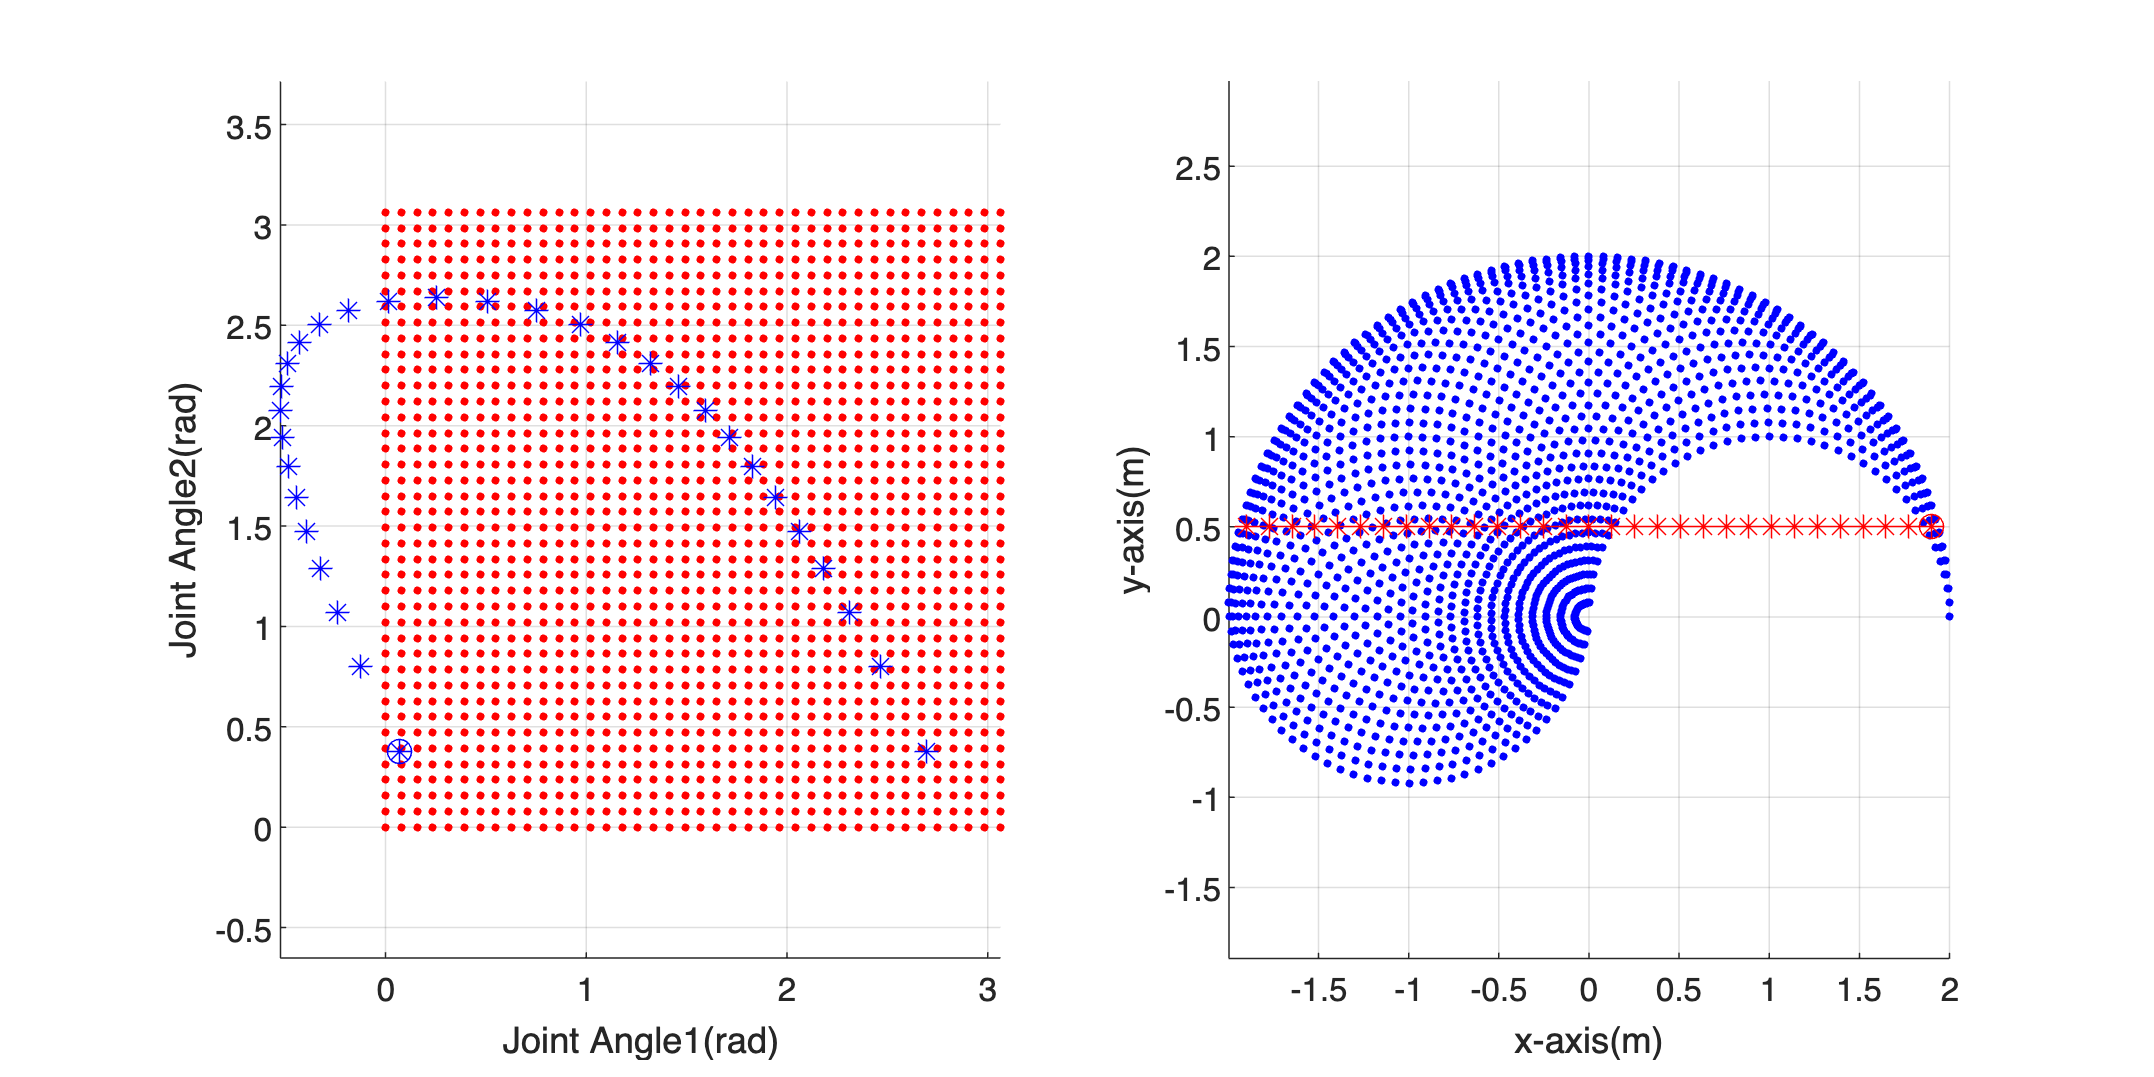

% 笛卡尔空间轨迹（无规划）
clc
clear
close all

% ++++++++++++++++++++++++++++++++++++++++++++++++
% 机器人
% Robot by DH parameters
%           theta d   a  alpha offset      
L(1) = Link([0    0   1   0    0]);
L(2) = Link([0    0   1   0    0]);
robot = SerialLink(L, 'name', 'Bot_2links');

% 为每一个关节设置旋转角度限制
% 为了后面显示
JL1u = pi;
JL1d = 0;
JL2u = pi;
JL2d = 0;

% 产生NxN的网格
N = 20;
N = 40;
theta1 = JL1d : (JL1u - JL1d)/N : JL1u;
theta2 = JL2d : (JL2u - JL2d)/N : JL2u;
[t1, t2] = meshgrid(theta1, theta2);

% 创建关节空间网格对应的笛卡尔空间坐标变量；
x = zeros(size(t1));
y = zeros(size(t2));

% ++++++++++++++++++++++++++++++++++++++++++++++++
% 关节空间中绘图
figure('position',[0,0,1200,600]);
subplot(1,2,1); 
view([0.40 90.00]); hold on; grid; axis equal
xlabel('Joint Angle1(rad)');  ylabel('Joint Angle2(rad)');

% 绘制关节空间中的网格，并计算对应的笛卡尔空间坐标
for n = 1:1:N
    for m = 1:1:N
        plot3(t1(n,m), t2(n,m), 0, 'r.','MarkerSize',8);    % 绘图
        T = robot.fkine([t1(n,m) t2(n,m)]);                 % 正运动学
        P = T.t;                                            % 齐次坐标变换矩阵中取x,y
        x(n,m) = P(1);
        y(n,m) = P(2);
    end
end

% 生成笛卡尔空间中一个直线，大约M个点
M = 30;
Xs = -1.9;
Xe = 1.9;

tx = Xs: (Xe-Xs)/M : Xe;
ty = 0.5 * ones(size(tx));

% 计算这些点在关节空间对应的数值，数值IK
Mask = [1; 1; 0; 0; 0; 0];

% IK计算的初值合理化(在指定的区域里)
q0 = [0,0]; % 手动给初值
Te = transl(tx(1), ty(1), 0);     % 末端位置确定的T矩阵；
q = robot.ikine(Te,'mask', Mask,'q0', q0);
if q(1)< 0
    q(1) = q(1) + pi; 
end
if q(2)< 0
    q(2) = q(2) + pi; 
end
q0 = q;

% 在关节空间中绘制这些直线上的点，并强调末端点
for m = 1:1:max(size(tx))
    Te = transl(tx(m), ty(m), 0);               % 末端位置确定的T矩阵；
    q = robot.ikine(Te,'mask', Mask,'q0', q0);  % 计算IK
    q0 = q;                                     % 更新q0
    plot3(q(1), q(2), 0, 'b*','MarkerSize',8);  % 绘制每一个点
end
plot3(q(1), q(2), 0, 'bo','MarkerSize',8);      % 再绘制一次最后一个点

% ++++++++++++++++++++++++++++++++++++++++++++++++
% 笛卡尔空间中绘图 
subplot(1,2,2); 
view([0.40 90.00]); hold on; grid; axis equal
xlabel('x-axis(m)');  ylabel('y-axis(m)');

% 绘制网格点
for n = 1:1:N
    for m = 1:1:N
        plot3(x(n,m), y(n,m), 0, 'b.','MarkerSize',8);
    end
end

% 绘制直线，并强调最后一个点
n = max(size(tx));
plot3(tx, ty, zeros(n), 'r*', 'MarkerSize',8);
plot3(tx(n), ty(n), 0, 'ro','MarkerSize',8);

% 释放内存空间
clear all;